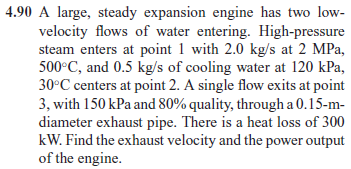

# given

u = symunit;
Qdot = -300*u.kW;

# inflow properties

% -----------------------
% superheated vapor water
mdot1 = 2.0*u.kg/u.s;
p1 = 2*u.MPa;
T1 = 500*u.Celsius;
h1 = 3467.55*u.kJ/u.kg;
% -----------------------
% saturated liquid water
mdot2 = 0.5*u.kg/u.s;
p2 = 120*u.kPa;
T2 = 30*u.Celsius;
h2 = 125.77*u.kJ/u.kg;
% -----------------------

# outflow properties

% -----------------------
% liquid-vapor water mix
p3 = 150*u.kPa;
T3 = 111.37*u.Celsius;
x3 = 0.80;
vf3 = 0.001053*u.m^3/u.kg;
vfg3 = 1.15828*u.m^3/u.kg;
v3 = vf3+x3*vfg3;
hf3 = 467.08*u.kJ/u.kg;
hfg3 = 2226.46*u.kJ/u.kg;
h3 = hf3+x3*hfg3;
% -----------------------
D3 = 0.15*u.m;
A3 = sympi*D3^2/4;

# conservation of mass

mdot3 = mdot1+mdot2;
V3 = mdot3*v3/A3;
V3_vpa = vpa(V3, 5)

$$V3\_vpa = 131.24\,\frac{m}{s}$$

# conservation of energy

syms Wdot;
Wdot = solve(Qdot+mdot1*h1+mdot2*h2 == Wdot+mdot3*(h3+V3^2/2));
Wdot = rewrite(simplify(Wdot), u.kW);
Wdot_vpa = vpa(Wdot, 6)

$$Wdot\_vpa = 1055.84\,\mathrm{kW}$$